# 3D Quadcopter Modelling and Simulation

% parameters
l = 0.24; % m
m = 1; % kg
g = 9.81; % m/s^2
I_xx = 0.01; % kgm^2
I_yy = 0.01; % kgm^2
I_zz = 0.02; % kgm^2
K_f = 1.87*10^-6; 
K_m = 1.87*10^-6;

% inputs 
U_1 = 0;
U_2 = 0;
U_3 = 0;
U_4 = 0; 

% state space for motor speed
A = [1/(4*K_f) 0 1/(2*K_f) 1/(4*K_m);
    1/(4*K_f) -1/(2*K_f) 0 -1/(4*K_m);
    1/(4*K_f) 0 -1/(2*K_f) 1/(4*K_m);
    1/(4*K_f) 1/(2*K_f) 0 -1/(4*K_m)];

t0 = 0; % start time
dt = 0.001; % step time
tf = 4; % final time

% Define time vector 
t = t0:dt:tf;

% Length of time array so we know the number of integration steps to make
N = length(t);

% Create placeholder arrays of zeros for the solution and the first derivative
x = zeros(1,N);
x_dot = zeros(1,N);
y = zeros(1,N);
y_dot = zeros(1,N);
z = zeros(1,N);
z_dot = zeros(1,N);
phi = zeros(1,N);
phi_dot = zeros(1,N);
theta = zeros(1,N);
theta_dot = zeros(1,N);
psi = zeros(1,N);
psi_dot = zeros(1,N);

% Set initial conditions
x(1) = 0;
x_dot(1) = 0;
y(1) = 0;
y_dot(1) = 0;
z(1) = 0;
z_dot(1) = 0;
phi(1) = 0;
phi_dot(1) = 0;
theta(1) = 0;
theta_dot(1) = 0;
psi(1) = 0;
psi_dot(1) = 0;

% loop through time steps using euler integration
for i = 1:N-1
    W = A * [U_1; U_2; U_3; U_4]; % compute motor speeds
    w_r = -W(1) + W(2) - W(3) + W(4);

    x_ddot = (-U_1/m)*(cos(phi(i))*sin(theta(i))*cos(psi(i)) + sin(psi(i))*sin(phi(i)));
    x_dot(i+1) = x_dot(i) + x_ddot*dt;
    x(i+1) = x(i) + x_dot(i)*dt;
    
    y_ddot = (-U_1/m)*(cos(phi(i))*sin(theta(i))*sin(psi(i)) - sin(theta(i))*sin(phi(i)));
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;

    z_ddot =  g - (U_1/m)*(cos(phi(i))*cos(theta(i)));
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;

    phi_ddot = 0;
    phi_dot(i+1) = phi_dot(i) + phi_ddot*dt;
    phi(i+1) = phi(i) + phi_dot(i)*dt;

    theta_ddot = 0;
    theta_dot(i+1) = theta_dot(i) + theta_ddot*dt;
    theta(i+1) = theta(i) + theta_dot(i)*dt;

    psi_ddot = 0;
    psi_dot(i+1) = psi_dot(i) + psi_ddot*dt;
    psi(i+1) = psi(i) + psi_dot(i)*dt;
end

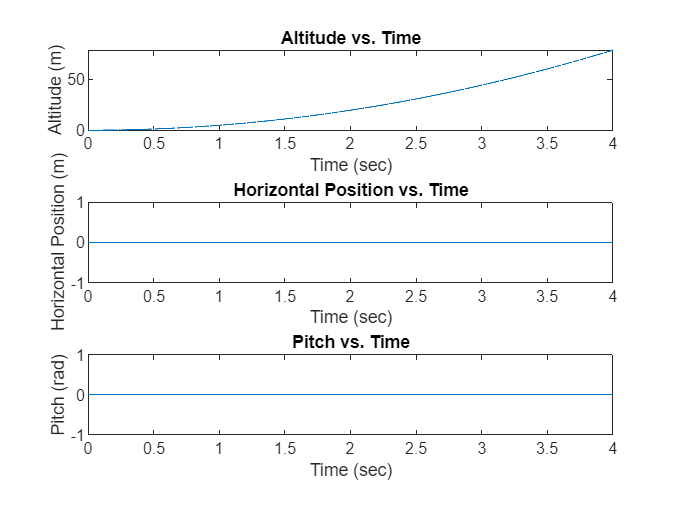

% plot data
subplot(3,1,1)
plot(t, z)
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")

subplot(3,1,2)
plot(t, y)
title("Horizontal Position vs. Time")
xlabel("Time (sec)")
ylabel("Horizontal Position (m)")

subplot(3,1,3)
plot(t, phi)
title("Pitch vs. Time")
xlabel("Time (sec)")
ylabel("Pitch (rad)")

% PID controller gains
Kp1 = 800; Ki1 = 300; Kd1 = 25;
Kp2 = 110; Ki2 = 50; Kd2 = 3;
Kp3 = 16; Ki3 = 10; Kd3 = 10;
Kp4 = 8; Ki4 = 10; Kd4 = 2;

% desired states
z_des = 1;
phi_des = 2;
theta_des = 2;
psi_des = 2;

% initialize error vectors and constants
z_error = zeros(N, 1);
I_1 = 0;
phi_error = zeros(N, 1);
I_2 = 0;
theta_error = zeros(N, 1);
I_3 = 0;
psi_error = zeros(N, 1);
I_4 = 0;

% loop through time steps using euler integration
for i = 1:N-1    
    % PID controller for alititude (U_1)
    z_error(i) = z_des - z(i);
    P_1 = Kp1 * z_error(i);
    I_1 = I_1 + Ki1 * z_error(i) * dt;
    D_1 = 0;
    if i > 1
        D_1 = (Kd1 * (z_error(i) - z_error(i-1)) / dt);
    end
    U_1 = P_1+I_1+D_1;

    % PID controller for roll (U_2)
    phi_error(i) = phi_des - phi(i);
    P_2 = Kp2 * phi_error(i);
    I_2 = I_2 + Ki2 * phi_error(i) * dt;
    D_2 = 0;
    if i > 1
        D_2 = (Kd2 * (phi_error(i) - phi_error(i-1)) / dt);
    end
    U_2 = P_2+I_2+D_2;

    % PID controller for pitch (U_3)
    theta_error(i) = theta_des - theta(i);
    P_3 = Kp3 * theta_error(i);
    I_3 = I_3 + Ki3 * theta_error(i) * dt;
    D_3 = 0;
    if i > 1
        D_3 = (Kd3 * (theta_error(i) - theta_error(i-1)) / dt);
    end
    U_3 = P_3+I_3+D_3;

    % PID controller for yaw (U_4)
    psi_error(i) = psi_des - psi(i);
    P_4 = Kp4 * psi_error(i);
    I_4 = I_4 + Ki4 * psi_error(i) * dt;
    D_4 = 0;
    if i > 1
        D_4 = (Kd4 * (psi_error(i) - psi_error(i-1)) / dt);
    end
    U_4 = P_4+I_4+D_4;

    W = A * [U_1; U_2; U_3; U_4]; % compute motor speeds
    w_r = W(1) - W(2) + W(3) - W(4);

    x_ddot = (-U_1/m)*(cos(phi(i))*sin(theta(i))*cos(psi(i)) + sin(psi(i))*sin(phi(i)));
    x_dot(i+1) = x_dot(i) + x_ddot*dt;
    x(i+1) = x(i) + x_dot(i)*dt;
    
    y_ddot = (-U_1/m)*(cos(phi(i))*sin(theta(i))*sin(psi(i)) - sin(theta(i))*sin(phi(i)));
    y_dot(i+1) = y_dot(i) + y_ddot*dt;
    y(i+1) = y(i) + y_dot(i)*dt;

    z_ddot =  g - (U_1/m)*(cos(phi(i))*cos(theta(i)));
    z_dot(i+1) = z_dot(i) + z_ddot*dt;
    z(i+1) = z(i) + z_dot(i)*dt;

    phi_ddot = 0;
    phi_dot(i+1) = phi_dot(i) + phi_ddot*dt;
    phi(i+1) = phi(i) + phi_dot(i)*dt;

    theta_ddot = 0;
    theta_dot(i+1) = theta_dot(i) + theta_ddot*dt;
    theta(i+1) = theta(i) + theta_dot(i)*dt;

    psi_ddot = 0;
    psi_dot(i+1) = psi_dot(i) + psi_ddot*dt;
    psi(i+1) = psi(i) + psi_dot(i)*dt;
end

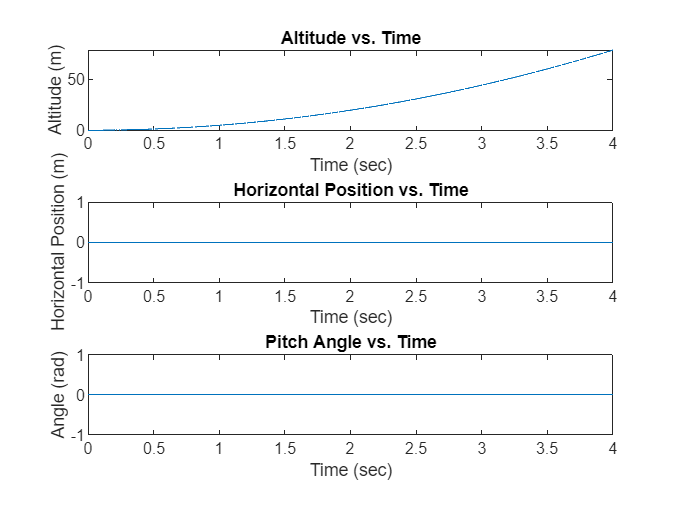

% plot data
%subplot(3,1,1)
plot(t, z)
title("Altitude vs. Time")
xlabel("Time (sec)")
ylabel("Altitude (m)")

%subplot(3,1,2)
plot(t, phi)
title("Roll Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")

%subplot(3,1,3)
plot(t, theta)
title("Pitch Angle vs. Time")
xlabel("Time (sec)")
ylabel("Angle (rad)")